# Distributedness of the signal direction explains the effect size of noise correlations on spatial and directional asymptotic SNR

org = Org; org.init;

pred_table = org.corr_table('asymp_ratio', true, true);

var_names = {'Variance of normalized signal', 'Number of neurons',...
    'Pop. signal sparsity', 'Pop. noise sparsity',...
    'area between corr pca signal loadings', 'area between cov pca signal loadings',...
    'Variance of signal', 'Eff. number of cov modes', 'Eff. number of corr modes',...
    'avg_signal', 'Number of trials', 'Eff. number of noise modes'};
vars_used = {'signal_var_norm', 'num_neurons',...
    'signal_density', 'noise_density',...
    'corr_cos2_area', 'cos2_area',...
    'signal_var', 'loadings_ipr', 'corr_loadings_ipr',...
    'avg_signal', 'num_trials', 'eigen_noise_ipr'};
metrics_used = {'pearson', 'pearson_p', 'adjr2', 'pearson_agg', 'pearson_p_agg', 'adjr2_agg'};

pred_table = pred_table(vars_used, metrics_used);
pred_table = sortrows(pred_table,'adjr2','descend')

pred_table = 12×6 table
                         pearson     pearson_p       adjr2      pearson_agg    pearson_p_agg    adjr2_agg
                         ________    __________    _________    ___________    _____________    _________

    signal_var_norm       0.75619    1.5917e-14       0.5657      0.83146        0.0028652       0.65274 
    num_neurons          -0.54098    9.2923e-07      0.28255     -0.61452         0.058698       0.29984 
    corr_cos2_area       -0.41678    0.00027078       0.1619     -0.73568         0.015299       0.48388 
    cos2_area            -0.37072     0.0013477      0.12511     -0.53504          0.11102       0.19706 
    signal_density       -0.32194     0.0058201   

writetable(pred_table, 'events_figs/f5_supplements/asymp_predictors.xlsx');

figure;
org.correlogram('signal_var_norm', 'asymp_ratio', true, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations signal_var_norm vs. asymp_ratio: adj. R^2 = 0.653
Pearson: 0.831, p = 2.865243e-03, **
Spearman: 0.636, p = 5.444507e-02, n.s.
Kendall: 0.511, p = 4.662257e-02, *


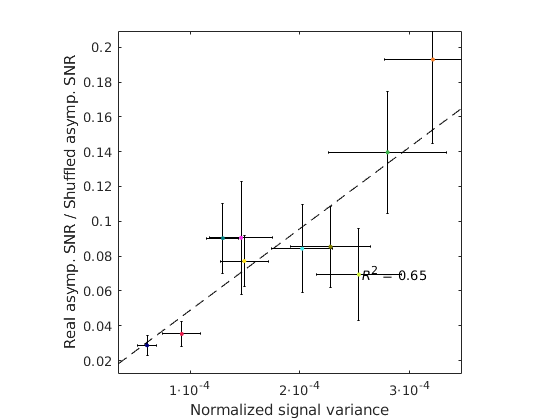

axis square
set(gca, 'XTick', [1 2 3]*1e-4);
Utils.fix_exponent(gca, 'x', 0);
ylabel 'Real asymp. SNR / Shuffled asymp. SNR'
xlabel 'Normalized signal variance'
Utils.printto('events_figs/f5_events', 'signal_var_norm_snr_ratio_correlation.pdf');

var_name = 'signal_var_norm';
var_label = 'Normalized signal variance';
mouse_low = 'Mouse2021';
mouse_high = 'Mouse2026';
yl_ = [0 6e-4];

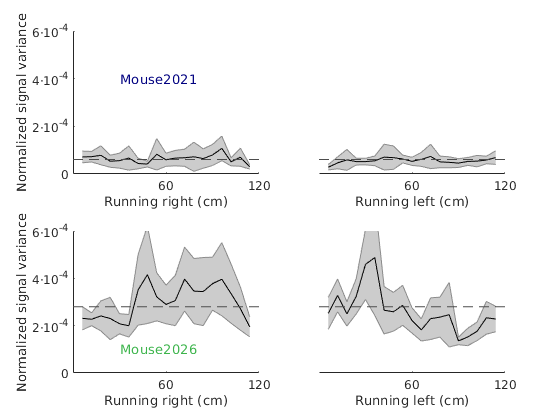

figure;

subplot(2,2,1);
mouse_name = mouse_low;
[m,s]=org.mouse_by_bins(var_name, {mouse_name, 'restrict'});
mean_nsv = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax=gca;
ax.XTick = [10 20];
ax.XTickLabel={'60','120'};
ylim(yl_);
Utils.fix_exponent(gca, 'y', 0);
ylabel(var_label);
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 4e-4, mouse_name, 'Color', m_color);
l_ = refline(0, mean_nsv);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right (cm)'

subplot(2,2,2);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_nsv);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim(yl_);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'60','120'};
ax.YAxis.Visible = 'off';
xlabel 'Running left (cm)'



subplot(2,2,3);
mouse_name = mouse_high;
[m,s]=org.mouse_by_bins(var_name, {mouse_name, 'restrict'});
mean_nsv = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax = gca;
ax.XTick = [10 20];
ax.XTickLabel = {'60', '120'};
ylim(yl_);
Utils.fix_exponent(gca, 'y', 0);
ylabel(var_label);
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 1e-4, mouse_name, 'Color', m_color);
l_ = refline(0, mean_nsv);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right (cm)'

subplot(2,2,4);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_nsv);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim(yl_);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'60','120'};
ax.YAxis.Visible = 'off';
xlabel 'Running left (cm)'
Utils.printto('events_figs/f5_events', 'nsv_by_bin.pdf');

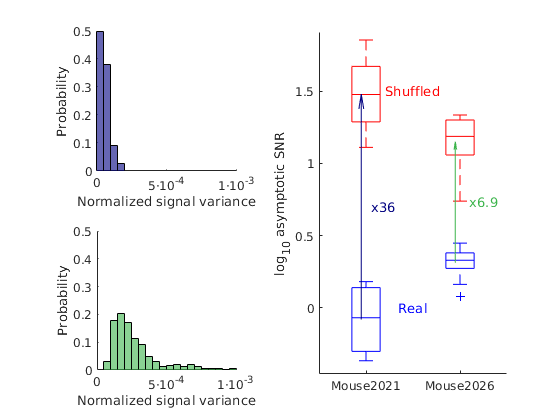

figure;
x_ = org.mouse_all_sess(var_name, {mouse_low, 'restrict'});
x_ = x_(:);
x_(isnan(x_)) = [];

y_ = org.mouse_all_sess(var_name, {mouse_high, 'restrict'});
y_ = y_(:);
y_(isnan(y_)) = [];

bin_width = 5e-5;
subplot(2,2,1);

m_color = DecodeTensor.mcolor({mouse_low});
m_color = m_color{1};
text(0.1*500, 0.2, mouse_low, 'Color', m_color); hold on;
histogram(x_, 'BinWidth', bin_width, 'FaceColor', m_color, 'Normalization', 'probability');
xlabel(var_label);
ylabel 'Probability'
axis square;
ax1 = gca;
ax1.Box = 'off';
%ax1.XTick = [];


subplot(2,2,3);
m_color = DecodeTensor.mcolor({mouse_high});
m_color = m_color{1};
text(0.1*500, 0.2, mouse_high, 'Color', m_color); hold on;
histogram(y_, 'BinWidth', bin_width, 'FaceColor', m_color, 'Normalization', 'probability');
xlabel(var_label);
ylabel 'Probability'
axis square;
ax2 = gca;
ax2.Box = 'off';
linkaxes([ax1 ax2]);
xlim([0 1e-3]);

Utils.fix_exponent(subplot(2,2,1), 'x', 0);
Utils.fix_exponent(subplot(2,2,3), 'x', 0);

subplot(2,2, [2 4]);
get_prop = @(p, m) org.sess_prop.(p)(strcmp(org.mouse, m));
get_mouse = @(m) org.mouse(strcmp(org.mouse, m));

boxplot(log10([get_prop('asymp_snr', mouse_low);...
    get_prop('asymp_snr', mouse_high)]),...
    [get_mouse(mouse_low), get_mouse(mouse_high)],...
    'Colors', 'b', 'Symbol', '+');
hold on;
boxplot(log10([get_prop('asymp_snr_shuf', mouse_low);...
    get_prop('asymp_snr_shuf', mouse_high)]),...
    [get_mouse(mouse_low), get_mouse(mouse_high)],...
    'Colors', 'r', 'Symbol', '+');
ylabel 'log_{10} asymptotic SNR'
text(1.5, 0, 'Real', 'Color', 'b', 'HorizontalAlignment','center');
text(1.5, 1.5, 'Shuffled', 'Color', 'r', 'HorizontalAlignment','center');

drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:} );
m_color = DecodeTensor.mcolor({mouse_low});
m_color = m_color{1};
b = mean(log10(get_prop('asymp_snr', mouse_low)));
t = mean(log10(get_prop('asymp_snr_shuf', mouse_low)));
drawArrow([1 1]-0.05,[b t], 'Color', m_color);
text(1 + 0.05, (b+t)/2, sprintf('x%.2g', 10^(t-b)), 'Color', m_color);

m_color = DecodeTensor.mcolor({mouse_high});
m_color = m_color{1};
b = mean(log10(get_prop('asymp_snr', mouse_high)));
t = mean(log10(get_prop('asymp_snr_shuf', mouse_high)));
drawArrow([2 2]-0.05,[b t], 'Color', m_color);
text(2 + 0.1, (b+t)/2, sprintf('x%.2g', 10^(t-b)), 'Color', m_color);

set(gca, 'Box', 'off');

Utils.printto('events_figs/f5_events', 'signal_var_norm_histograms.pdf');

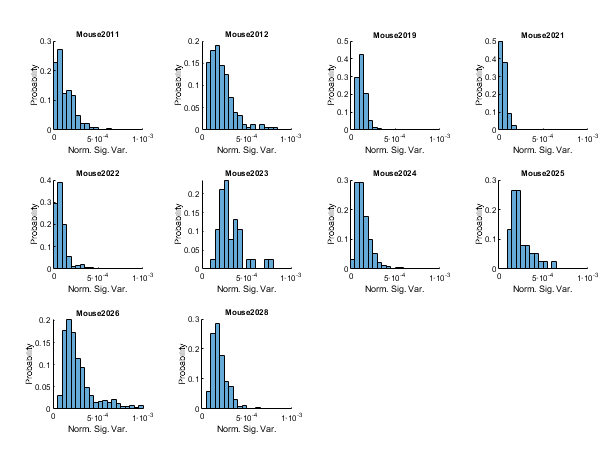

m = SessManager.highqual_mice;

p = Pub(16, 12, 'rows', 3, 'columns', 4, 'hspacing', 0.08, 'vspacing', 0.11);

for m_i = 1:numel(m)
    p.panel(m_i, 'xlab', 'Norm. Sig. Var.', 'ylab', 'Probability', 'letter', '', 'title', m{m_i});
    
    my_mouse = m{m_i};
    
    NSV = org.mouse_all_sess('signal_var_norm', {my_mouse, 'restrict'});
    NSV = NSV(:);
    NSV(isnan(NSV)) = [];
    
    bin_width = 5e-5;%0.01;
    histogram(NSV, 'BinWidth', bin_width, 'Normalization', 'probability');
    xlim([0 1e-3]);
    axis square;
    ax2 = gca;
    ax2.Box = 'off';
    Utils.fix_exponent(gca, 'x', 0);
end
p.format;
Utils.printto('events_figs/f5_supplements', 'NSV_histograms_per_mouse.pdf');

## Normalized signal variance for head direction and the asymptotic ratio

figure; org.correlogram('hd_svn', 'hd_asymp_ratio', true, true, true);

Using only 34 out of 110 sessions
Mouse-aggregated correlations hd_svn vs. hd_asymp_ratio: adj. R^2 = 0.863
Pearson: 0.939, p = 5.295725e-04, ***
Spearman: 0.952, p = 1.140873e-03, **
Kendall: 0.857, p = 1.736111e-03, **


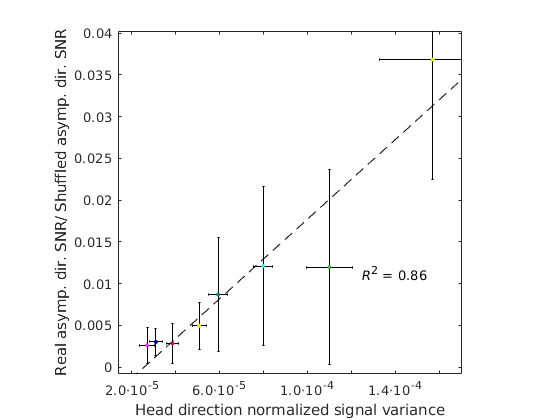

xlabel 'Head direction normalized signal variance'
ylabel 'Real asymp. dir. SNR/ Shuffled asymp. dir. SNR'
Utils.fix_exponent(gca, 'x', 1);
axis square
Utils.printto('events_figs/f5_supplements', 'HD_asymp_ratio_svn.pdf');